clear all

addpath (genpath('/home/johnpaustian/matlab/ClassifyImages'));

addpath (genpath('/home/johnpaustian/scratch/Imagery'));

addpath (genpath('/home/johnpaustian/matlab/Sandbox'))

%read and save a test image as a .tif

% i = imread('GAL010_00142.JPG'); 
% 
% imshow(i)
% 
% imwrite(i,'image1.tif') 

%Run GUI

%   RUN_GUI 

clear all

load image1_GTOutput_20190726T104846; % load from home  

imwrite(output.groundTruth.matrix,'groundtruth.tif','tiff')


input.IMAGE = 'image1.tif';
input.GRNDTRUTH = 'groundtruth.tif';
input.nclasses  = 4;    % number of classes
input.crossval  = 1;    % 1 = k-fold cross validation; 0,[] = none.
input.thresh    = [];   % 100,[] = no threshold; alph = alpha% chi^2 c.i.
input.prefilt   = 1;    % [] or 0 = no prefilt, 1 = 1st, 2 = 2nd, 3 = 3rd 
                         % order neighborhoods
input.smoothing = 3;    % 0,[] = none; 1 = nonlin filter; 2 = PLR; 3 = MRF
input.iter      = 5;    % # iters in PLR or MRF.
input.beta      = 10;   % beta (regularization parameter) for MRF.

tic
spv_output = ImageClassify(input);

10 PERCENT RANDOM REMOVAL CROSS VALIDATION.
Percent misclassified after 10 removals = 5.5687
MRF iter = 1
MRF iter = 2
MRF iter = 3
MRF iter = 4
MRF iter = 5


toc

Elapsed time is 32.595327 seconds.


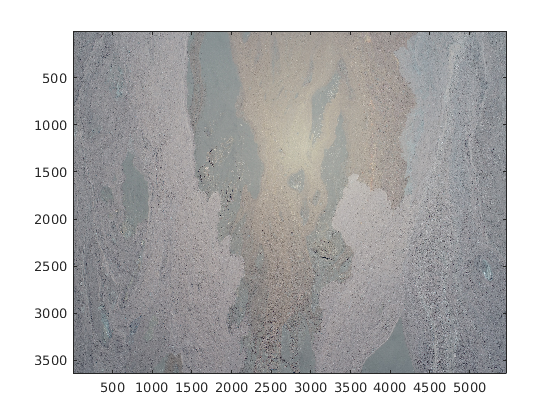

Image = spv_output.Image;
GrndTruth = spv_output.GrndTruth;
Classification = spv_output.Classification;

if isempty(input.thresh)==1
    input.thresh = -1;
end
if 0<input.thresh && input.thresh<100
    input.nclasses=input.nclasses+1;
end


i = figure;
    imagesc(Image)

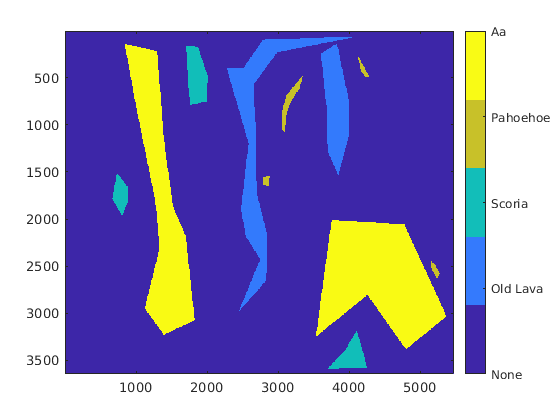

gt = figure;
    imagesc(GrndTruth)
    c1 = colorbar; caxis([0,input.nclasses]);
    colormap(parula(5))
    c1.Ticks = [0 1 2 3 4];
    c1.TickLabels = {'None','Old Lava','Scoria','Pahoehoe','Aa'};

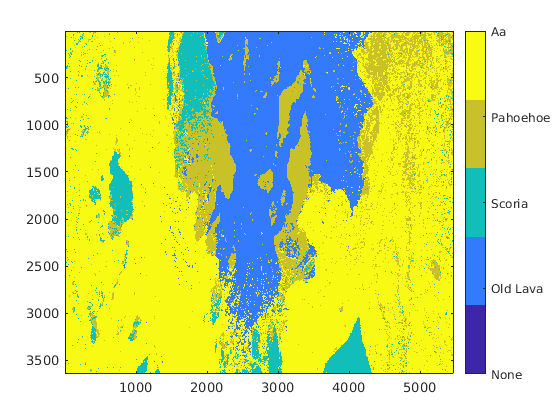

classify = figure;
    imagesc(Classification)
    c2 = colorbar; caxis([0,input.nclasses]);
    c2.Ticks = [0 1 2 3 4];
    colormap(parula(5))
    c2.TickLabels = {'None','Old Lava','Scoria','Pahoehoe','Aa'};

% save supervised classification to file

save('spv_class.mat','Classification');

## Translating into a groundTruth object




% Create ground truth data source from image file

   imageFiles = {'image1.tif'};

    dataSource = groundTruthDataSource(imageFiles);  


%Define labels used to specify ground truth

load image1_GTOutput_20190726T104846.mat; % load from home

new_names = {'OldLava','Scoria', 'Pahoehoe', 'Aa'}; % MATLAB doesn't like spaces or apostrophes in variable names
output.groundTruth.name = new_names; % overwrite the old names

ldc = labelDefinitionCreator(); % create empty label definition
for ii = 1 : numel(output.groundTruth.name)
    addLabel( ldc, output.groundTruth.name{ii}, labelType.PixelLabel ); % insert the new_names for labels
end
labelDefs = create( ldc ); % create the label table


% Label data

% Write the pixel-labeled image to jpg
labeled_image = Classification;
filename = 'pixel_labeled_image.tiff';
imwrite( labeled_image, filename, 'TIFF', 'Compression', 'none', 'WriteMode', 'overwrite' );

dataFile = {filename}; % make a cell
labelData = table( dataFile, 'VariableNames', {'PixelLabelData'} );


% Create the GroundTruth object

spv_gTruth = groundTruth(dataSource,labelDefs,labelData);

save('spv_gTruth');

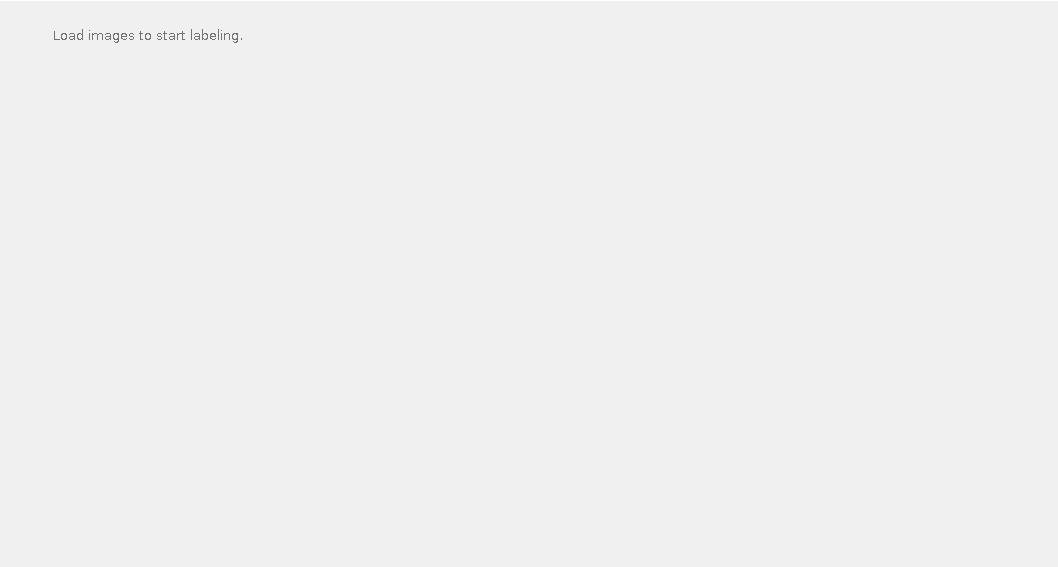

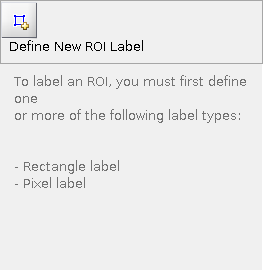

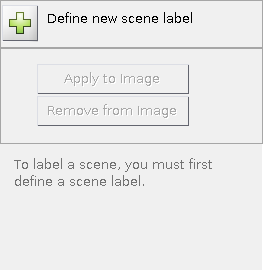

imageLabeler()